# **Bivariate rectangular density on a two-dimensional domain **

Let $f(\mathbf{x})$ be the target density on a $d=2$-dimensional domain, $\mathbf{x} = [-18,18] \times [-3,3] \subset \mathbb{R}^{2}$. Haario et al. (1999) define the interior domain $S=[-0.5,0.5] \times [-3,3]$ and set 


$$f(\mathbf{x})= \begin{cases}
     \; 36 & \text{if $x \in S$}\\
     \; 1 & \text{\;\;otherwise}
    \end{cases}
$$


The Figure below is copied from Haario et al. (1999) and presents an unscaled one-dimensional projection of the density of the target distribution. The wording "unscaled" implies that the target density does not integrate to one. This is inconsequential for MCMC simulation as the normalization constant does not matter as it cancels in the computation of the Metropolis acceptance probability, $\alpha(\mathbf{x}_\text{p}\vert \mathbf{x}_{(i)})$.  

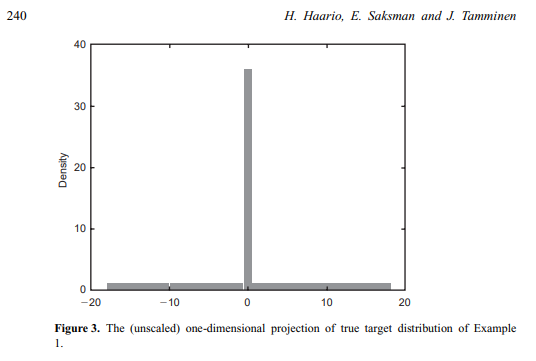

function lik = rectangle_lik(x)
% 2-dimensional rectangular target distribution
%   Haario, H., E. Saksman, and J. Tamminen (1999), Adaptive proposal 
%       distribution for random walk Metropolis algorithm. Computational 
%       Statistics 14, 375–395, https://doi.org/10.1007/s001800050022
% The vector d enters as a horizontal vector: x = (x_1,...,x_d)
% Function also works if X is a Nxd matrix of N proposals of x

[N,d] = size(x);                    % Dimensions of candidate vector x
if d ~= 2
    error(['DREAM_PACKAGE:rectangle_lik:Candidate vector ' ...
        'should be two-dimensional'])
end
lik = ones(N,1);                    % Initialize likelihood of R
s = x(:,1) >= -1/2 & x(:,1) <= 1/2; % Is candidate vector x in domain 
                                    % S: [-.5,.5] x [-3,3] of 
                                    % R: [-18,18] x [-3,3] ?
lik(s) = 36;                        % If in S, then f(x) = 36

end